**Desplazamiento en el tiempo de señales de tiempo discreto**

Definición de variables

N=50;
d=0; %desplazamiento

if d < 0
    un=ones(1,N+1); %escalón unitario
    n=d:N+d; %vector de tiempo discreto
else
    un=[zeros(1,d) ones(1,N-d+1)]; %escalón unitario
    n=0:N; %vector de tiempo discreto
end

Desplazamiento en el tiempo de una señal periodica

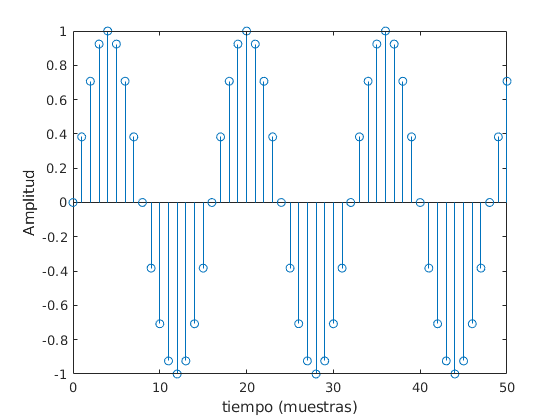

Am=1;
fr=16;
xn=Am*sin(2*pi*(1/fr)*(n-d)).*un;
figure
stem(n,xn)
xlabel('tiempo (muestras)')
ylabel('Amplitud')

Desplazamiento en el tiempo de una señal exponencial

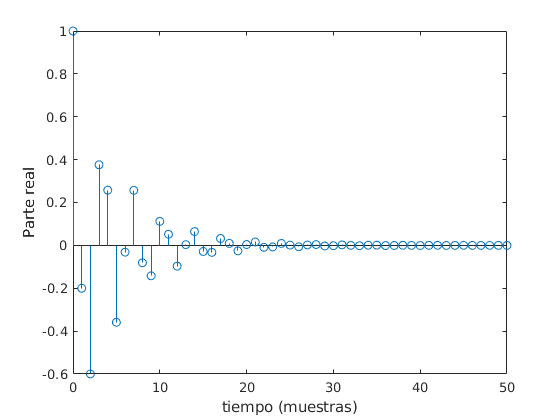

RE=-0.2;
IM=0.8;
A=RE+1i*IM;
xn=A.^(n-d).*un;
figure
stem(n,real(xn))
xlabel('tiempo (muestras)')
ylabel('Parte real')

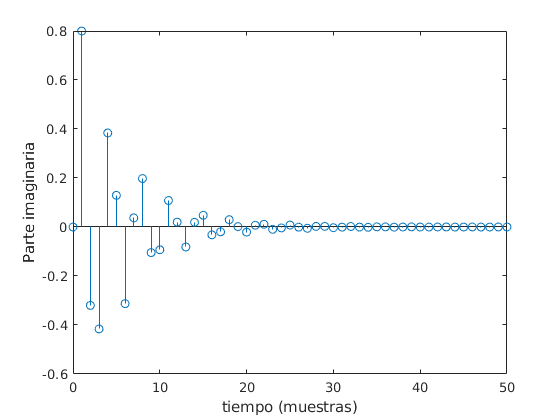

figure
stem(n,imag(xn))
xlabel('tiempo (muestras)')
ylabel('Parte imaginaria')

Observe la forma y los valores de las señales, ¿Cómo cambian de acuerdo con el valor de la variable d?